# 数据可视化 小组Project

钟诚        16307110259

周璐鹿    15307110349

张奕朗    16307130242

清理运行环境

clear
clc
close all

## 局部仿射变换测试

读取测试图片

testImg = imread('../test_images/ape.png');
testImg = double(testImg) / 256;

反向仿射变换：将图像中部两个$32\times 32$的矩形分别顺时针、逆时针旋转${45}^{\circ }$

[H,W] = size(testImg,[1,2]);
testTransMap = zeros(H,W);
testTransMap(H/2-31:H/2,W/2-31:W/2) = 1;
testTransMap(H/2+1:H/2+32,W/2+1:W/2+32) = 2;
testTransform = cell(1,2);
testTransform{1} = [1/sqrt(2), 1/sqrt(2), 0 ;
                   -1/sqrt(2), 1/sqrt(2), 0 ;
                       0     ,     0    , 1 ];
testTransform{2} = [1/sqrt(2),-1/sqrt(2), 0 ;
                    1/sqrt(2), 1/sqrt(2), 0 ;
                       0     ,     0    , 1 ];

调用函数，进行测试

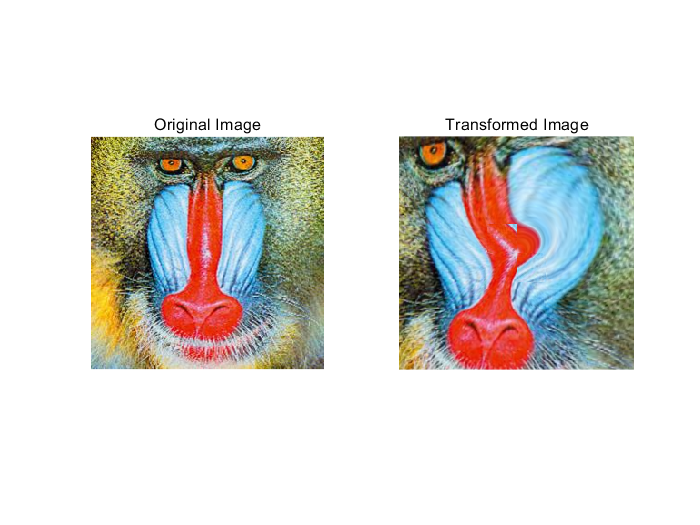

localAffine_inv(testImg,testTransform,testTransMap,'dist_e',2,'visualize',true);